clear
path = [0 0; 0 0.5; 0 1; 0 1.5; 0 2; 0.5 2; 1 2; 1.5 2; 2 2; 2.5 2; 3 2; 3.5 2; 4 2; 4.5 2; 5 2;5 1.5; 5 1; 5 0.5; 5 0; 4.5 0; 4 0;3.5 0;3 0;2.5 0;2 0;1.5 0;1 0;0.5 0];
robotInitialLocation = path(1,:);
robotGoal = path(end,:);
initialOrientation = 0;
robotCurrentPose = [robotInitialLocation, initialOrientation]';

robot = differentialDriveKinematics("TrackWidth", 0.5, "VehicleInputs", "VehicleSpeedHeadingRate");

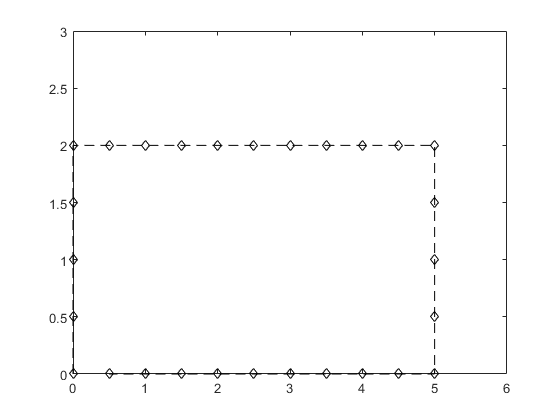

figure
plot(path(:,1), path(:,2),'k--d')
xlim([0 6])
ylim([0 3])

controller = controllerPurePursuit;

controller.Waypoints = path;

controller.DesiredLinearVelocity = 0.6;

controller.MaxAngularVelocity = 2;

controller.LookaheadDistance = 0.3;

goalRadius = 0.1;
distanceToGoal = norm(robotInitialLocation - robotGoal);

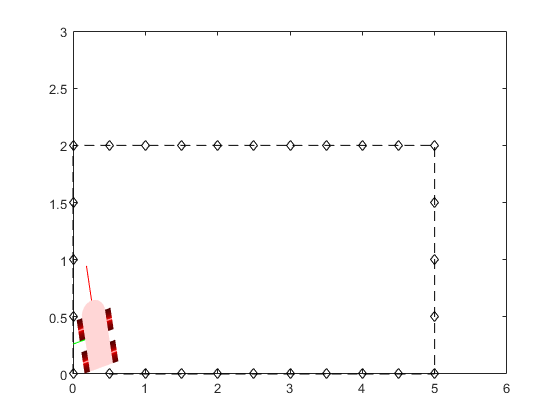

% Initialize the simulation loop
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
frameSize = robot.TrackWidth/0.8;

while( distanceToGoal > goalRadius )
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
    % Update the plot
    hold off
    
    % Plot path each instance so that it stays persistent while robot mesh
    % moves
    plot(path(:,1), path(:,2),"k--d")
    hold all
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", frameSize);
    light;
    xlim([0 6])
    ylim([0 3])
    
    waitfor(vizRate);
end